`【例`**1-1**`】命令窗口的操作示例。输入变量，在命令窗口输入以下代码。`


a=[1 2 3;4 5 6;7 8 9;10 11 12];
disp(a);

`【例`**1-2**`】把当前文件夹设置成自定义目录的方法如下所示。在`**MATLAB**`操作桌面的右上方或当前文件夹浏览器的左上方有一个当前文件夹设置区，如图`**1.15**`所示。它包括`**Current Directory**`和`**Browse for folder**`。用户在`**Current Directory**`中直接输入待设置的目录名，或借助`**Browse for folder**`和鼠标选择待设置目录即可。`  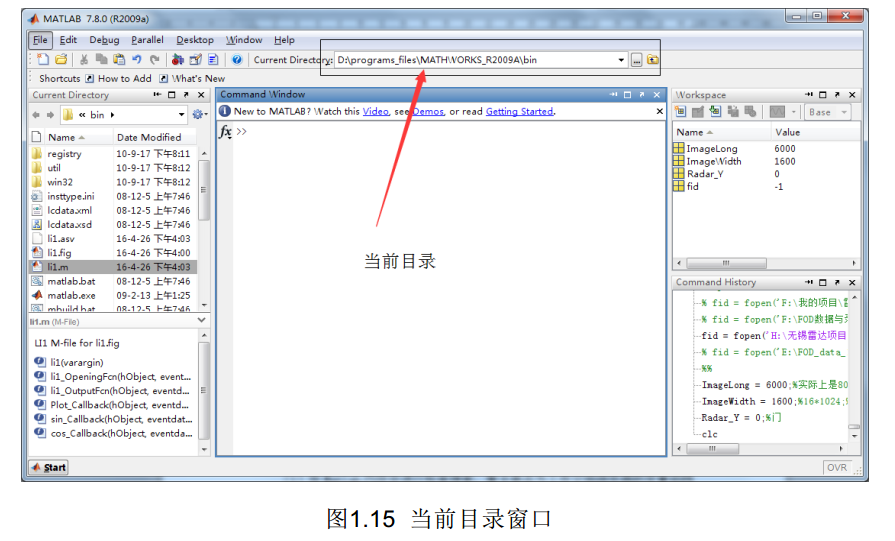

`例如要在`**D:\programs_files\MATHWORKS_R2009A\bin **`目录下添加文件夹`**mywork**`，只要按如图`**1.16**`所示进行操作即可。`

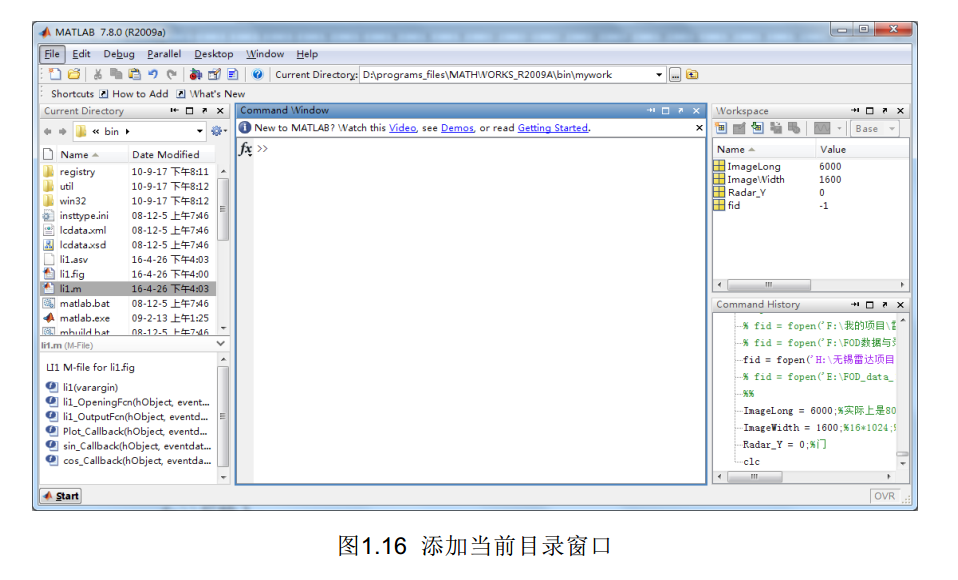

`【例`**1-3**`】求一个数是否为素数的脚本文件，其`**MATLAB**`脚本文件的代码如下。`

x=input('Please input a number:');
if x==1
   disp('既不是素数也不是合数')
   isSushu = -1;
   return;
end
isSushu = 1;
for i=2:x-1
  if mod(x, i)==0
     isSushu = 0;
     disp(i);
    end
end
if isSushu
   disp([num2str(x) ' is a prime number'])
else
   disp([num2str(x) ' is a not prime number'])
end

`【例`**1-4**`】编写`**M**`函数实现判断输入一个数是否为素数。 `**MATLAB**`代码的如下。函数文件：`

**function isSushu = sushu( x )**

**%sushu **`判断一个数是否是素数`

**% sushu(x)**

**% **`输入： `**x **`输入要判断的数`

**% **`输出： `**isSushu 0**`表示不是素数， `**1**`表示是素数`**,-1**`表示既不是素数也不是合数`

**%**

**if x==1**

**   disp('**`既不是素数也不是合数`**')**

**   isSushu = -1;**

**   reurn;**

**end**

**isSushu = 1;**

**for i=2:x-1**

**    if mod(x, i)==0**

**        isSushu = 0;**

**    end**

**end**

  `则在`**MATLAB**`中构建如下的脚本文件。`  

x=input('Please input a number:');
if sushu(x)
   disp([num2str(x) ' is a prime number'])
else
   disp([num2str(x) ' is a not prime number'])
end

`【例`**1-5**`】显示窗口中变量的信息`  

**MATLAB**`代码如下：`

a=[1 2 3;4 5 6];
who a

`【例`**1-6**`】显示窗口中变量的详细信息`  

**MATLAB**`代码如下：`  

a=[1 2 3;4 5 6];
whos a

`【例`**1-7**`】清除内存中的变量，并检测是否清除`  

**MATLAB**`代码如下：`  

a=[1 2 3;4 5 6];
who a
clear a
who a

`【例`**1-8**`】查询矩阵的维数`  

**MATLAB**`代码如下：`  

a=[1 2 3;4 5 6]
[m n] = size(a)

`【例`**1-9**`】查询向量的长度`

**MATLAB**`代码如下：`  

a=[1 2 3 4 5 6]
n = length(a)

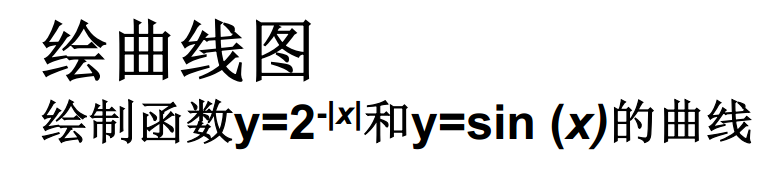

x=-2*pi:pi/180:2*pi;
figure,plot(x,2.^(-abs(x)),'r:',x,sin(x),'bo');

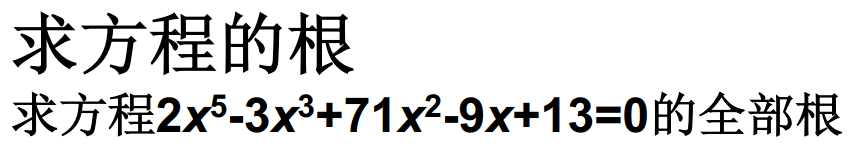

p=[2,0,-3,71,-9,13];
x=roots(p)

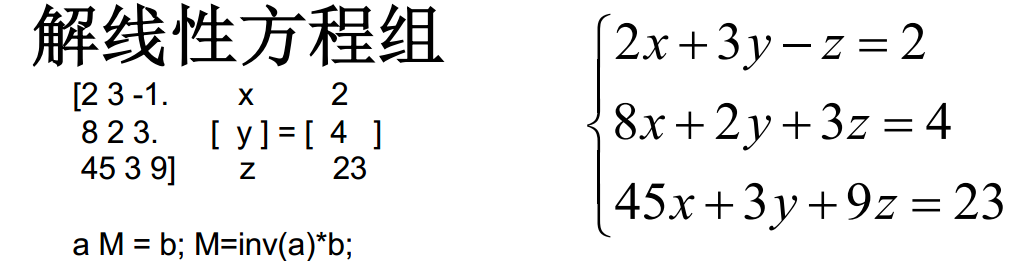

`法`**1**`： 调用求逆矩阵函数`**inv**  

a=[2,3,-1;8,2,3;45,3,9]; %系数矩阵
b=[2;4;23]; %常数项列向量
x=inv(a)*b

`法`**2**`： 左除运算`  

a=[2,3,-1;8,2,3;45,3,9]; %系数矩阵
b=[2;4;23]; %常数项列向量
x=a\b

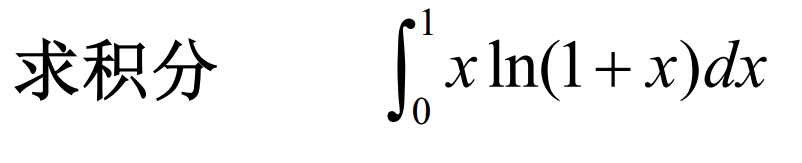

`法`**1**`： 调用`**quad**  

quad('x.*log(1+x)',0,1)

`法`**2**`： 符号计算`  

syms x
int(x*log(1+x),0,1)